# **Circuitos**

clear all; close all; clc;

**Cálculo de Impedâcia**

T = 4;
w = (2*pi)/T;
s = w*j;

zl = impInd(2,s)

zl = 0.0000 + 3.1416i

zc = impCap(1/8,s)

zc = 0.0000 - 5.0930i

**Potência Média**

% [result] = potenciaMedia( p_de_t, w)

**Representações de Grandezas Complexas**

% funcTempo(grandeza_em_retangular, w)
% funcExp

**Resistências Equivalentes**

% Uma alternativa à função parallelRes
% (que funciona para 2 resistores):
parallel = @(r1,r2) (r1*r2)/(r1 + r2);

%exemplo:

z1 = 4*(10^4);
z2 = -(1000/3)*j;

zt = parallelRes({z1,z2})
zt = parallel(z1,z2);
polarAng(zt)

**Cáculo de valores RMS (root mean square)**

syms('t')

w = 1000

w = 1000

v = 3*cos(w*t +1.625)

$$v = 3\,\cos\left(1000\,t+\frac{13}{8}\right)$$

V = 3;

Vrms = valueRMS(v , w)

Vrms = 2.1213


3/sqrt(2) % no caso de senoides basta dividir o valor médio pela raíz de 2

ans = 2.1213

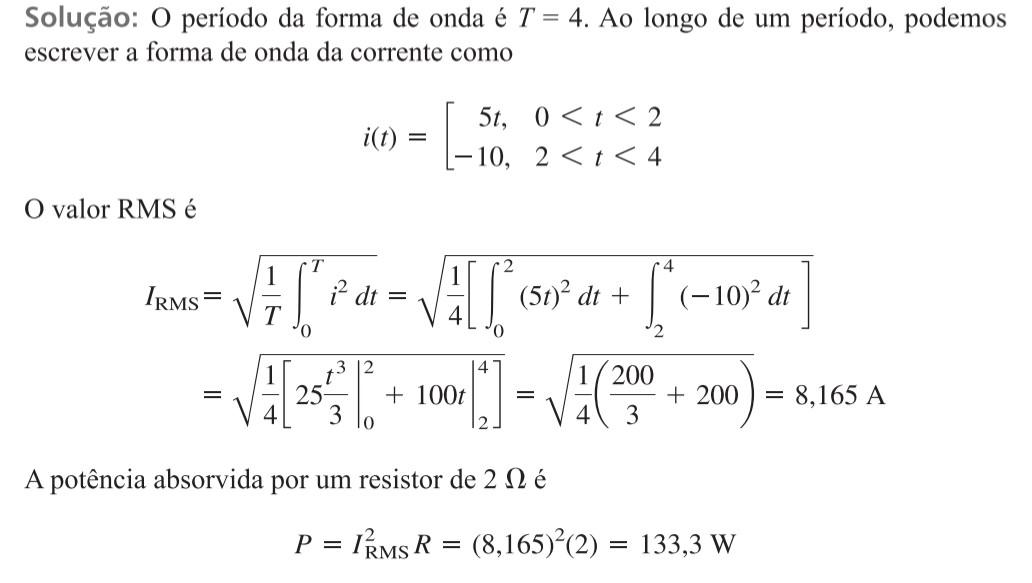

i = piecewise( 0<t<2, 5*t, 2<t<4, -10 )

$$i = \left\{ \begin{array}{cl} 5\,t & \text{ if }t\in \left(0,2\right)\\ -10 & \text{ if }t\in \left(2,4\right) \end{array}\right.$$

T = 4;
w = (2*pi)/T;
Irms = valueRMS(i , w)

Irms = 8.1650


R = 2;

P = (Irms^2)*R

P = 133.3333

### **Sistemas de equações**

Ex: Q3 - P3 - 2018 

Dados Iniciais

clear all; close all; clc;

syms('I1','I2','I3');

w = 4;

z1 = 20;
z2 = 14;
z3 = 10;
zl = impInd(2,w);
zc = impCap(1/8,w);

Vf = polar2recDeg(30,-45);
Ix = I1 - I2;
V0 = zc*(I2-I3);

Equacionando o circuito por LKT e simplificando as equações

% LKT em I1
eq1 = Vf - z1*I1 -z2*(I1 - I2) - 3*V0 == 0;
simplify(eq1)

$$ans = I_{1}\,\left(17-17\,\mathrm{i}\right)+I_{3}\,\left(3+3\,\mathrm{i}\right)+15\,\sqrt{2}\,\mathrm{i}=I_{2}\,\left(10-4\,\mathrm{i}\right)$$


% LKT em I2
eq2 = 3*V0 + z2*(I1 - I2) - zl*I2 - z3*(I2 - I3) - zc*(I2 - I3) == 0;
simplify(eq2)

$$ans = 7\,I_{1}+I_{3}\,\left(5+2\,\mathrm{i}\right)=I_{2}\,\left(12+6\,\mathrm{i}\right)$$


% sabemos também que:
eq3 = I3 == 2*Ix;
simplify(eq3)

$$ans = 2\,I_{1}=2\,I_{2}+I_{3}$$

Checando se equações são Equivalentes

% LKT em I1
eq1_test1 = polar2recDeg(30,-45) - 20*I1 -14*(I1 - I2) - 3*V0 == 0;
simplify(eq1_test1)

$$ans = I_{1}\,\left(17-17\,\mathrm{i}\right)+I_{3}\,\left(3+3\,\mathrm{i}\right)+15\,\sqrt{2}\,\mathrm{i}=I_{2}\,\left(10-4\,\mathrm{i}\right)$$


eq1_test2 = 34*I1 - (14+j*6)*I2 + j*6*I3 == polar2recDeg(30,-45);
simplify(eq1_test2)

$$ans = 34\,I_{1}+I_{2}\,\left(-14-6\,\mathrm{i}\right)+6\,I_{3}\,\mathrm{i}=\sqrt{2}\,\left(15-15\,\mathrm{i}\right)$$


eq1_test3 = 34*I1 - (14+j*6)*I2 + j*6*I3 == polar2recDeg(30,-45) + 0.00003; % diferente
simplify(eq1_test3)

$$ans = 34\,I_{1}+I_{2}\,\left(-14-6\,\mathrm{i}\right)+6\,I_{3}\,\mathrm{i}=\frac{5970994387242213}{281474976710656}-15\,\sqrt{2}\,\mathrm{i}$$


% 1 se forem equivalentes, 0 se não
isAlways(eq1 == eq1_test1)

ans = logical
   1


isAlways(eq1 == eq1_test2)

ans = logical
   1


isAlways(eq1 == eq1_test3)

ans = logical
   0


Resolvendo sistema para fins de conferência

% Resolvendo sistema de equações
sol = solve( [eq1, eq2, eq3], [I1, I2, I3] );
I1_sol = double(sol.I1);
polarAng(I1_sol)

0.92649-1.0363i = (1.3901) ∠ -48.2020°  ou  -0.8413


I2_sol = double(sol.I2);
polarAng(I2_sol)

0.51129-0.86472i = (1.0046) ∠ -59.4055°  ou  -1.0368


I3_sol = double(sol.I3);
polarAng(I3_sol)

0.83041-0.34314i = (0.8985) ∠ -22.4515°  ou  -0.3919


Definindo matrizes manualmente e resolvendo

Z = [17 - 17*j, -(10-4*j), (3+3*j)  ; 
     7, -(12+6*j), (5+2*j)  ;
      2, -2, -1 ]

Z =   17.0000 -17.0000i -10.0000 + 4.0000i   3.0000 + 3.0000i
   7.0000 + 0.0000i -12.0000 - 6.0000i   5.0000 + 2.0000i
   2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i


  
I = [I1 I2 I3].'

$$I = \left(\begin{array}{c} I_{1}\\ I_{2}\\ I_{3} \end{array}\right)$$


V = [ -sqrt(2)*15*j  ;
      0  ;
      0 ]

V =    0.0000 -21.2132i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


  
eq_a = Z*I == V;

% Resolvendo sistema de matrizes
sol = solve( eq_a, [I1, I2, I3] );
I1_sol = double(sol.I1);
polarAng(I1_sol)

0.92649-1.0363i = (1.3901) ∠ -48.2020°  ou  -0.8413


I2_sol = double(sol.I2);
polarAng(I2_sol)

0.51129-0.86472i = (1.0046) ∠ -59.4055°  ou  -1.0368


I3_sol = double(sol.I3);
polarAng(I3_sol)

0.83041-0.34314i = (0.8985) ∠ -22.4515°  ou  -0.3919


Defiindo matrizes automaticamente e resolvendo

sistem = [eq1, eq2, eq3]

$$sistem = \left(\begin{array}{ccc} -34\,I_{1}+I_{2}\,\left(14+6\,\mathrm{i}\right)-6\,I_{3}\,\mathrm{i}+\sqrt{2}\,\left(15-15\,\mathrm{i}\right)=0 & 14\,I_{1}+I_{2}\,\left(-24-12\,\mathrm{i}\right)+I_{3}\,\left(10+4\,\mathrm{i}\right)=0 & I_{3}=2\,I_{1}-2\,I_{2} \end{array}\right)$$

[Z,V] = equationsToMatrix(sistem)

$$Z = \left(\begin{array}{ccc} -34 & 14+6\,\mathrm{i} & -6\,\mathrm{i}\\ 14 & -24-12\,\mathrm{i} & 10+4\,\mathrm{i}\\ -2 & 2 & 1 \end{array}\right)$$

$$V = \left(\begin{array}{c} \sqrt{2}\,\left(-15+15\,\mathrm{i}\right)\\ 0\\ 0 \end{array}\right)$$


I = [I1 I2 I3].'

$$I = \left(\begin{array}{c} I_{1}\\ I_{2}\\ I_{3} \end{array}\right)$$


eq_a = Z*I == V;

% Resolvendo sistema de matrizes
sol = solve( eq_a, [I1, I2, I3] );
I1_sol = double(sol.I1);
polarAng(I1_sol)
I2_sol = double(sol.I2);
polarAng(I2_sol)
I3_sol = double(sol.I3);
polarAng(I3_sol)

0.92649-1.0363i = (1.3901) ∠ -48.2020°  ou  -0.8413


0.51129-0.86472i = (1.0046) ∠ -59.4055°  ou  -1.0368


0.83041-0.34314i = (0.8985) ∠ -22.4515°  ou  -0.3919


[Convert linear equations to matrix form - MATLAB equationsToMatrix (mathworks.com)](https://www.mathworks.com/help/symbolic/sym.equationstomatrix.html)

**Minhas Funções**

function [resEquivalent] = parallelRes(resList)
%parallelRes(resList) tem como entrada uma lista de resistores
%(ou reatâncias) em paralelo e retorna o valor da resistência 
%(ou reatância) equivalente. Funciona para o cálculo de qualquer
%outra grandeza que siga a mesma fórmula, à exemplo capacitores
%em série.

    condutEquivalent = 0;
    for i = 1:length(resList)
        condutEquivalent = condutEquivalent + 1/resList{i};
    end

    resEquivalent = 1/condutEquivalent;

end

function [result] = impCap( capacitancia, s )
%impCap( capacitancia, s ) recebe como entrada o valor
% de capacitância do capacitor e "s", tal que:
% (s = a + j*w), 
% onde "w" é a a frequência angular (rd/s) da fonte
% e "a" é a frequência Neperiana (Np/s) da fonte
% A função retorna o valor de impedância sobre aquele capacitor.

result = 1/(s*capacitancia);

end

function [result] = impInd( indutancia, s )
%impInd( indutancia, s ) recebe como entrada o valor
% de indutância do intutor e "s", tal que:
% (s = a + j*w), 
% onde "w" é a a frequência angular (rd/s) da fonte
% e "a" é a frequência Neperiana (Np/s) da fonte
% A função retorna o valor de impedância sobre aquele indutor.

result = indutancia*s;

end


function [result] = valueRMS( func_de_t , w)
%valueRMS( func_de_t , w) recebe como entrada f(t) e a
%frequência angular, devolvendo o valor RMS.

    T = (2*pi)/w;
    quadrado = func_de_t^2;

    if isa(quadrado, 'double')
        integral = double(T);
    else
        integral = int( quadrado , 0, T );
    end
    
    result = double( sqrt( (1/T)*integral ) );

end

function [result] = potenciaMedia( p_de_t, w)
% potenciaMedia( p_de_t, w) calcula a potência mádia da função p(t).

    T = (2*pi)/w;
    
    if isa(p_de_t, 'double')
        result = p_de_t;
    else
        result = double( (1/T)*int(p_de_t, 0, T) );
    end
       
end

function [result] = funcTempo(grandeza_em_retangular, w)
% funcTempo(grandeza_em_retangular, w) transforma por exemplo a tensão V
% que está na forma retangular em uma função v(t)

    syms('t');
    result = abs(grandeza_em_retangular)*cos(w*t + angle(grandeza_em_retangular));
end